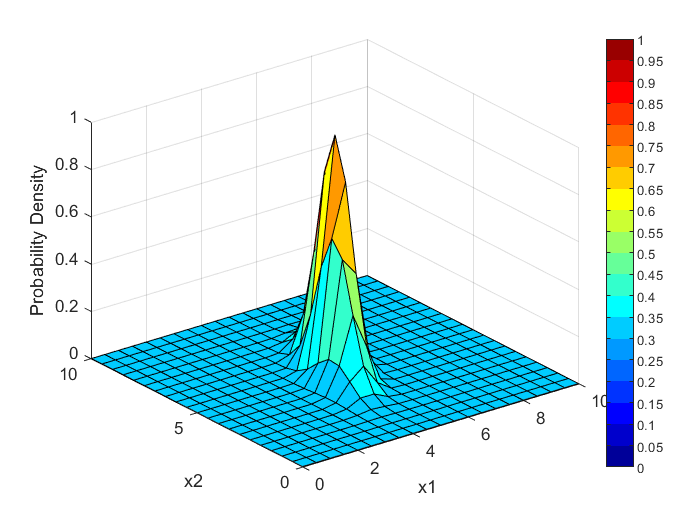

R =   [0   -0.0083
    0.0083         0
  -79.0542   12.4708];

mu = [5 5];
Sigma = [0.25 0.3; 0.3 1];
x1 = 0:0.5:10;
x2 = 0:0.5:10;
[X1,X2] = meshgrid(x1,x2);
X = [X1(:) X2(:)];
y = mvnpdf(X,mu,Sigma);
y(:) = normalize(y(:),1,"range");
y = reshape(y,length(x2),length(x1));
surf(x1,x2,y)
caxis([min(y(:))-0.5*range(y(:)),max(y(:))])
xlabel('x1')
ylabel('x2')
zlabel('Probability Density')

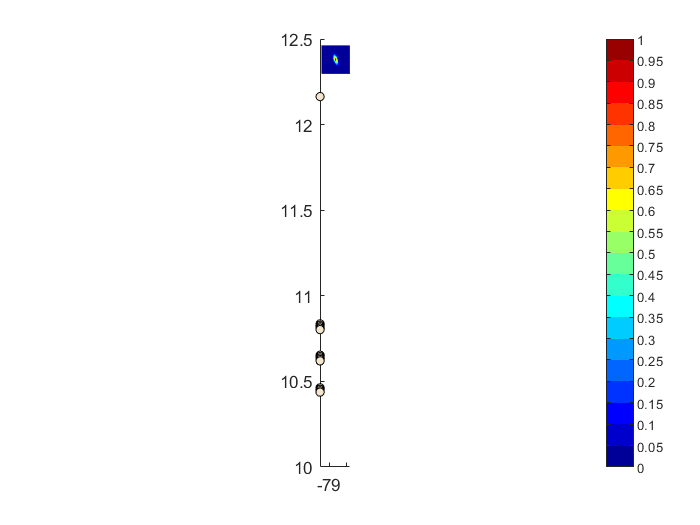

factor = 0;    
score = zeros(1,5);
occupation = 0.4;
samples = 500;

    breaks = [1 0.8 0.6 0.4 0.2 0];
    DistanceSampling = y(:);
    limit = round(length(DistanceSampling)*occupation);
    
    for i = 1 : 5
        
        dist1 = DistanceSampling < breaks(i);
        dist2 = DistanceSampling > breaks(i + 1);
        dist = DistanceSampling(logical(dist1.*dist2));
        len = length(dist);
        score(i) = (len/(limit - 1)) ^ factor * mean(dist);
        
    end
    
    score = score / sum(score);
    score = [0, round(score * samples)];    
    len = zeros(6, 1);
    sscore = cumsum(score);
    sampled = zeros(1, sscore(end));
    y2 = y;
    [y,idx]=sort(y2(:),'descend');
    
    for i = 1 : 5
        dist1 = DistanceSampling < breaks(i);
        dist2 = DistanceSampling > breaks(i + 1);
        dist = DistanceSampling(logical(dist1.*dist2));
        len(i + 1) = len(i) + length(dist);
        sampled(sscore(i) + 1 : sscore( i + 1 )) = randsample(len(i) + 1 : len( i + 1), score(i + 1), true);%muestrear con reemplazo   
    end
    y(:) = 0;
    y(sampled) = 1;
    y(idx) = y;
    sampled = find(y(:) == 1);

    
    Lat = NaN(1, length(sampled));
    Long = Lat;
    [Dim1, Dim2] = size(y);
    for i = 1 : length(sampled)
        col = fix(sampled(i)/Dim1);  % integer part
        row = rem(sampled(i), Dim1);  % remainder
        
        if row > Dim1 || col > Dim2
            disp(i)
        end
        
        [Long(i), Lat(i)] = pix2map(R, row, col);%!!
    end
    
            
figure(2)
        clf
        geoshow(y2, R, 'DisplayType', 'surface');
        contourcmap('jet',0 : 0.05 : 1, 'colorbar', 'on', 'location', 'vertical')
        geoshow(Lat, Long, 'DisplayType', 'Point', 'Marker', 'o', ...
            'MarkerSize', 5, 'MarkerFaceColor', [.95 .9 .8], 'MarkerEdgeColor', ...
            'black', 'Zdata', 2 * ones(length(Long), 1));  